# **Tutorial 1**: Introduction

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Context and objectives

`SDTlib` is a SIMULINK library to model multibody systems in the context of space vehicle engineering.

The multibody systems considered in the `SDTlib` are composed of $N_b$ rigid or flexible bodies (or links) $\mathcal A_i$, $i=1,\cdots N_b$ connected to each other by clamped joints or $N_j$ single-axis revolute/prismatic joints (primatic joints are introduced on the **full version** of the `SDTlib`). One can distinguish chain-like multibody systems (Fig.a), tree-like systems  (Fig.b) and closed kinematic chain systems  (Fig.c). 

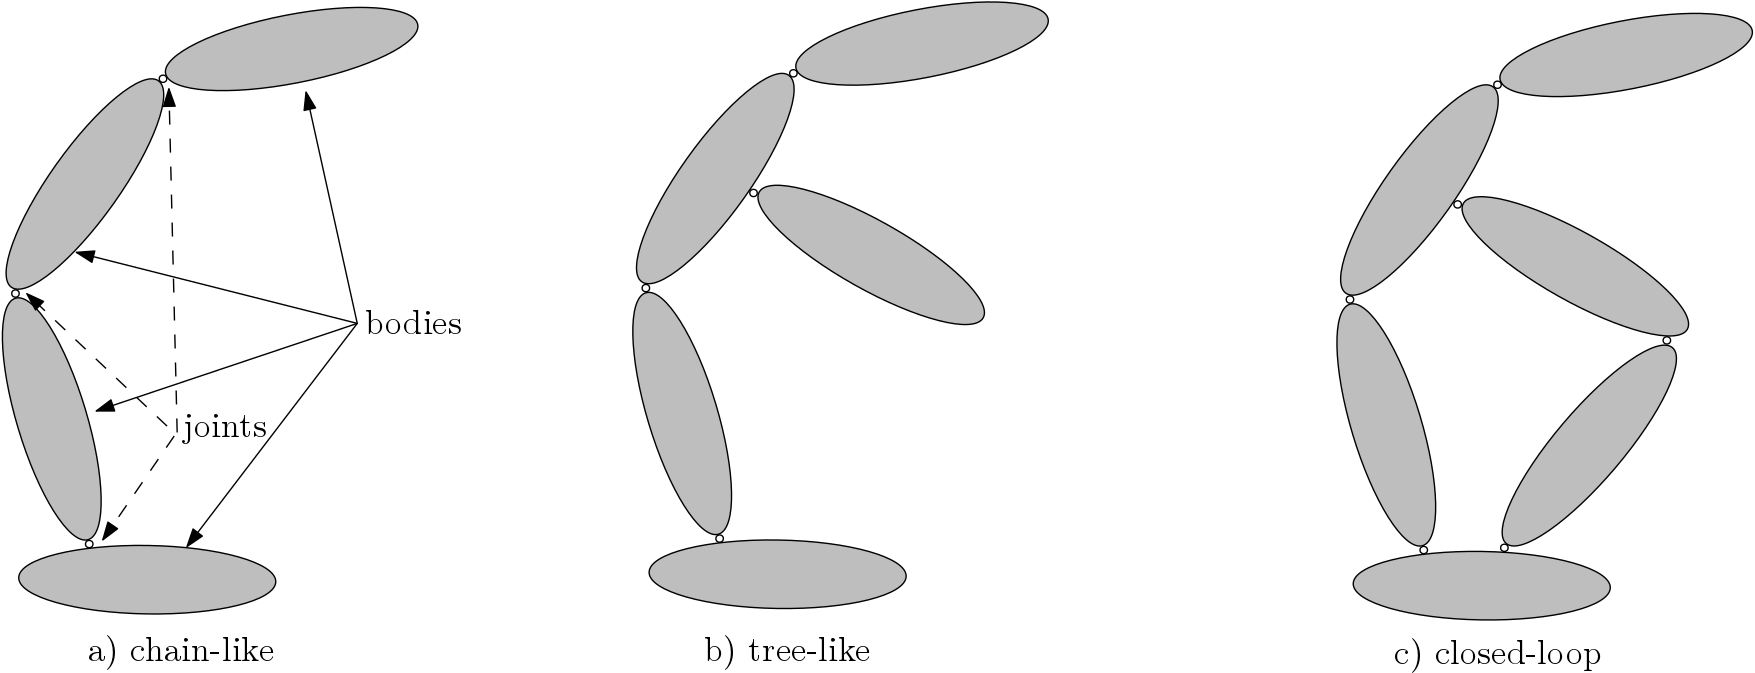

**Notations:**

-  $N_{dof}$ is the number of rigid degrees-of-freedom (d.o.f.) and $\mathbf{\theta}=[\theta_1,\theta_2,\cdots,\theta_{N_{j}}]^T$ is the **geometric configuration** vector: if the $i$-th joint is a revolute joint then $\theta_i$ is the angular configuration of the joint in $rad$. If the $i$-th joint is a prismatic joint then $\theta_i$ is the linear configuration of the joint in $m$. For an open-kinematic system (chain-like or tree-like): $N_{dof}=N_j+6$, i.e. the geometric configuration of the $N_j$ revolute or prismatic joints plus the $6$ d.o.fs (3 translations and 3 rotations) of the reference body (anyone particular body among the $N_b$ bodies),

- $\mathbf p_i$ , $i=1,\cdots N_b$ is the mechanical parameter vector of each body $\mathcal A_i$; i.e: the vector containing all the varying, uncertain or to be sized mechanical paremeters of the body (mass, inertia, centering, ...)

- $\mathbf \Delta=\{\mathbf p_1,\mathbf p_2,\cdots,\mathbf p_{N_b}\}$ is the whole **mechanical parameter** vector of the system,

- for flexible bodies, $\delta \mathbf x_i$ is the internal deformation d.o.f vector of the flexible body $\mathcal A_i$ and $\mathbf x_f=[\delta \mathbf x^T_1,\delta\mathbf x^T_2,\cdots,\delta\mathbf x^T_{N_b}]^T$ is the deformation d.o.f. vector of the whole system.

In all the cases, the objective of the **SDTlib **is to derive the linear model of the system dynamics for a given geometric configuration $\mathbf{\theta}_{ref}$ of the $N_{dof}$ rigid d.o.fs and around an  equilibrium characterized by:

$\mathbf \theta_{ref}$, $\dot{\mathbf{\theta}}_{ref}=\mathbf{0}$,  $\ddot \mathbf\theta_{ref}=\mathbf 0$, $\mathbf x_{f,ref}=\mathbf 0$, $\dot\mathbf x_{f,ref}=\mathbf 0$ and $\ddot\mathbf x_{f,ref}=\mathbf 0$.

Such a model is only valid for small variations ( $\delta\mathbf\theta=\mathbf\theta-\mathbf\theta_{ref}$) of the d.o.fs around the equilibrium configuration, small variation rates ( $\dot\mathbf\theta=\delta\dot\mathbf\theta$)  and small deformations of the flexible bodies ( $\mathbf x_f$, $\dot\mathbf x_f$).

The** main interest** of the `SDTlib` is the possibility to build this linear model, named $\mathbf M^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$ where $\mathrm s$ is the *Laplace *variable, of the multibody system $\mathcal S$ fully parameterized according to the:

- **geometric configuration**: $\mathbf \theta_{ref}$,

- **mechanical parametric configuration**: $\mathbf \Delta$.

The model $\mathbf M^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$ is computed once and for all and is fully compatible with `Matlab robust control toolbox` (it is an `uss`).

This model is built block by block from the various `SDTlib` blocks used to model each body and each joint. 

It is important to understand that the dynamic model $\mathbf M^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$(or the various sub-model) is the transfer between:

- the external wrenches (forces and torques) which can be applied to any body at any given points and the driving torques (forces) which can be applied inside any revolute (prismatic) joints,

- the  [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html'))  (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions) of bodies at any given points and the relative motion vectors of the joints : $\delta m_i=[\ddot\theta_i,\;\;\delta\dot\theta_i\;\; \delta\theta_i]^T$ ( $i=1,\cdots N_j$) .

Thus:

- since this model works for small motions around a given geometric configuration, it is assumed that the external wrenches and driving torques (forces) are small and null at the equilibrium (indeed: $\ddot\mathbf\theta_{ref}=\mathbf 0$). **Thus gravitationnal force/acceleration are not taken into account in the **`SDTlib,`

- the state vector $\mathbf x$ of $\mathbf M^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$ is composed of (i) the internal deformation  d.o.fs $\mathbf x_f$of each flexible body and their time-derivative $\dot\mathbf x_f$ and (ii) the relative (w.r.t. equilibrium) positions $\delta\mathbf \theta$ and velcities $\delta\dot{\mathbf\theta}$ od the rigid modes: $\mathbf x= [\delta\mathbf\theta,\;\; \delta\dot{\mathbf\theta},\;\;\mathbf x_f^T,\;\;\dot\mathbf x_f^T]^T$.  Thus the dynamic model $\mathbf M^{\mathcal S}(\mathbf \theta_{ref},\mathbf\Delta)$ for a rigid multi-body system includes only the $N_{dof}$ rigid modes of the system. $\delta\mathbf \theta$ and $\delta\dot{\mathbf\theta}$  are always in the outputs of the model to model, for instance ,  a local mechanism or a controller at a revolute (prismatic) joint or to take into account an Attitude and Orbit Control System (AOCS) on the reference body (that will be highlighted in the various tutorials).

**For closed kinematic chain systems**, the number of rigid and independent d.o.f.s is reduced due to the loop closure constraints:

- $\mathbf g(\mathbf \theta,\mathbf x_f)=\mathbf 0$ (on positions),

- $\frac{\partial \mathbf g}{\partial \mathbf \theta}^T\dot\mathbf\theta+\frac{\partial \mathbf g}{\partial \mathbf x_f}^T\dot\mathbf x_f=\mathbf 0$ (on velocities)

- $\frac{\partial \mathbf g}{\partial \mathbf \theta}^T\ddot\mathbf\theta+\frac{\partial \mathbf g}{\partial \mathbf x_f}^T\ddot\mathbf x_f+\underbrace{\frac{d}{dt}\left(\frac{\partial \mathbf g}{\partial \mathbf \theta}^T\right)\dot\mathbf\theta+\frac{d}{dt}\left(\frac{\partial \mathbf g}{\partial \mathbf x_f}^T\right)\dot\mathbf x_f}_{\mbox{non-linear terms}}=\mathbf 0$ (on accelerations)

These constraints $\mathbf g$ are non-linear equations and are not solved in the `SDTlib` and it is assumed that the user can provide a geometric configuration $\mathbf\theta_{ref}$ satisfying these constraints and the equilibrium conditions, i.e. $\mathbf g(\mathbf \theta_{ref},\mathbf 0)=\mathbf 0$. Then the `SDTlib` can be used to build a linear model which is valid for small variations around the configuration $\mathbf\theta_{ref}$ while satisfying the linearized loop closure constraints at the acceleration level:

$\frac{\partial \mathbf g}{\partial \mathbf \theta}^T\ddot\mathbf\theta+\frac{\partial \mathbf g}{\partial \mathbf x_f}^T\ddot\mathbf x_f=\mathbf 0$.

As a consequence, for closed kinematic chain systems, the linear model is only parameterized according to the mechanical parameter vector: $\mathbf M^{\mathcal S}(\mathrm s,\mathbf\Delta)$.

Finally, $\mathbf{M\!a}^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$ denotes the model where the motion vectors are reduced to their first $6$ components of the acceleration dual vectors. Thus  the input/output channels of this model are invertible. In the `SDTlib` documentation, the model from accelerations (input) to forces/torques (output) is called the **direct dynamic model **and is homegenous to mass ( $Kg$) and inertia ( $Kg\,m^2$ ) while the model from forces/torques (input) to accelerations (output) is called the** inverse dynamic model** (not to confused with the terminology "forward dynamics" and "inverse dynamics" commonly used in multi-body dynamics).

### First summary

- `SDTlib` is a tool that was designed for linear parametric modelling, frequency-domain analysis, **parametric robustness analyses** and/or **robust control design** purposes.

- **SDTlib** is not a tool that was designed for time-domain simulation purposes. Nevertheless, linear models can easily be simulated after linearization of the Simulink model (with the function `ulinearize`). The tutorial 12 of the **full version** of the `SDTlib (`[**Simulating a SDTlib-based model**](matlab:open('../Tutorial12/tutorial12.html'))***)*** is proposed to address this topic.

## 2. One-port dynamic model

In this section, the general multibody system context is restricted to the case where the system $\cal S$ is composed of a rigid body (the base $\mathcal B$) holding various single (rigid or flexible) bodies, called appendages ( $\mathcal A_i$). In the following Figure, the main body $\mathcal B$ is rigid and holds 2 flexible appendages:

- a solar pannel $\mathcal A_1$at point $P_1$ through a revolute joint,

- an antenna $\mathcal A_2$ at poiint $P_2$ though a clamped joint.

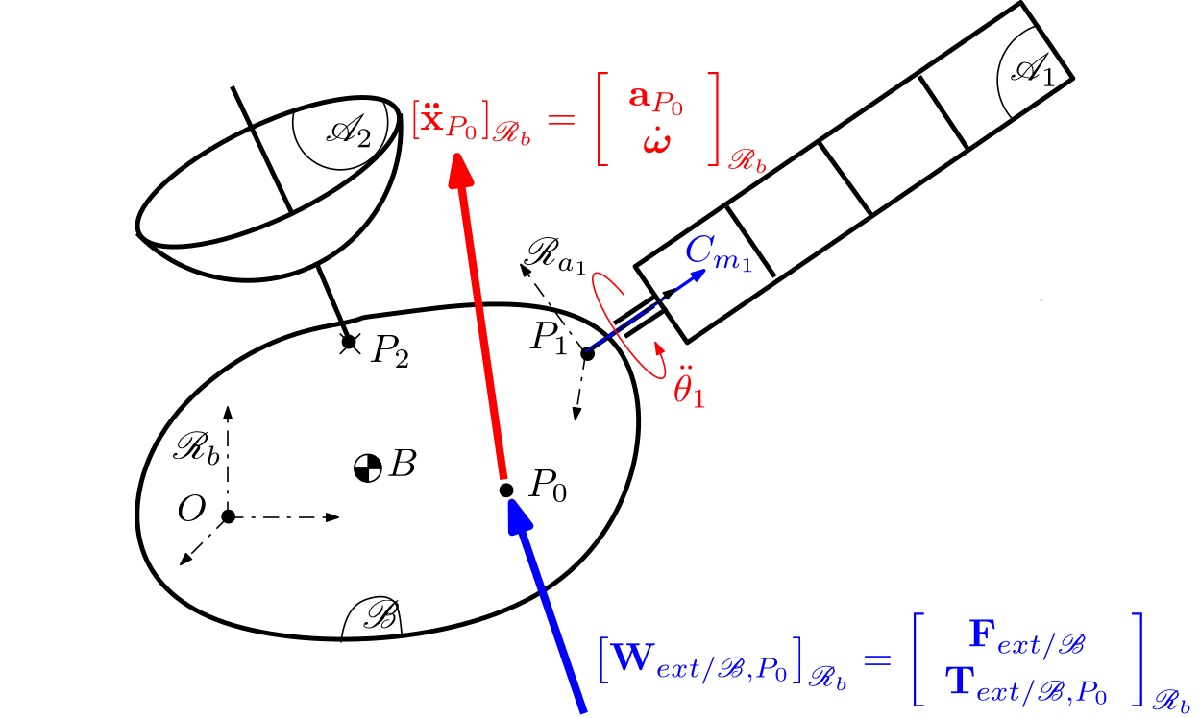

Furthermore, it is assumed that the appendages are only submitted to the interaction wrenches with the main body. **Finally this section also considers the models **$\mathbf M\!a^{*}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$** between wrenches and acceleration dual vector.**

**Notations:**

- $O$, $B$, $P_i$ are the reference point, the centre of mass and the connection points of the body $\mathcal B$, respectively,

- $\mathcal R_b$, $\mathcal R_{a_i}$ are the main body frame and the appendage $\#\;i$ body frame, respectively,

- $P_0$ is the point on $\mathcal B$ where is applied the $6$ component resultant wrench $\mathbf W_{ext/\mathcal B,P_0}$of external forces $\mathbf F_{ext/\mathcal B}$ ($3$ components, independent from the considered point since the main body is rigid) and torques $\mathbf T_{ext/\mathcal B,P_0}$ (3 components). This wrench is due to orbital disturbances, AOCS actuators,.... . $P_0$ is also the point where is considered the $6$ component dual acceleration twist $\mathbf{\ddot x}_{P_0}$ composed of the inertial translational acceleration $\mathbf a_{P_0}$ ( $3$ components)  of the main body at point $P_0$ and its angular acceleration $\mathbf{\dot\omega}$ ( $3$components, independent from the considered point since the main body is rigid),

- $C_{m_i}$ and $\ddot\theta_i$ are the in-joint driving torque and the relative acceleration of the revolute joint of the appendage $\mathcal A_i$.

Considering the example of the Figure above, the objective is to find the $7\times 7$ dynamic model  $[\mathbf M\!a^{\mathcal S}_{P_0}]_{\mathcal R_b}(\mathrm s,\theta_{1},\mathbf\Delta)$ and/or its inverse $[\mathbf M\!a^{\mathcal S}_{P_0}]^{-1}_{\mathcal R_b}(\mathrm s,\theta_{1},\mathbf\Delta)$ between $\mathbf{\ddot x}_{P_0}$ and $\ddot\theta_1$ on one side and $\mathbf W_{ext/\mathcal B,P_0}$ and $C_{m_1}$ on the other side. The notation of the model $[\mathbf M\!a^{\mathcal S}_{P_0}]_{\mathcal R_b}(\mathrm s,\theta_{1},\mathbf\Delta)$ includes the point $P_0$ where is written this model and the frame $\mathcal R_b$ where it is projected:    

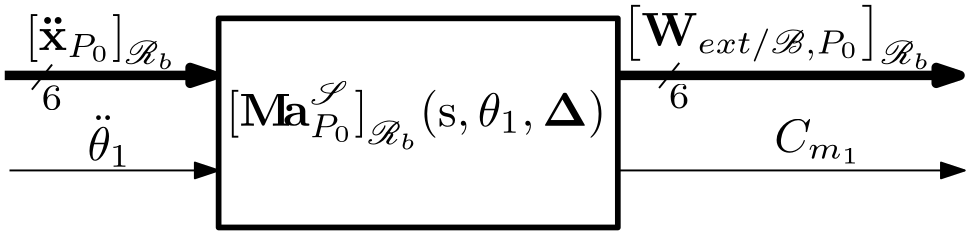                             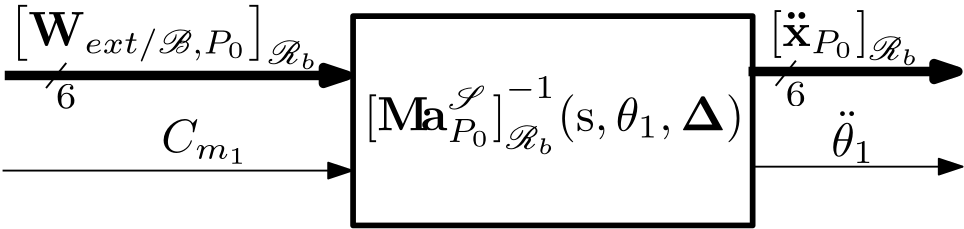

In sections 2.1 and 2.2 the clamped connection of one appendage to a main body is detailed in the single axis case (academic example on the spring-mass system) and the $6$ d.o.fs case, respectively.  The proposed solution is strongly linked to the **modal effective mass models** used in structural dynamics (see references) and renamed **one port model** in this documentation.

In section 2.3, it is shown that taking into account the revolute joint between the main body and the appendage can be easily solved by working on the **direct dynamic model**  $[\mathbf M\!a^{\mathcal S}_{P_0}]_{\mathcal R_b}(\mathrm s,\theta_{1},\mathbf\Delta)$ and that the inverse dynamic model $[\mathbf M\!a^{\mathcal S}_{P_0}]^{-1}_{\mathcal R_b}(\mathrm s,\theta_{1},\mathbf\Delta)$, required to design control laws, can be obtained by a simple inversion operation. 

Finally, an on-board angular mometum (due for instance to a reaction wheel system or more generally to a balanced wheel spinned at a constant angular rate as the appendage $\mathcal A_3$ depicted in the next Figure) can also be taken into account as  a dynamic appendage using the same formalism. See also the tutorial 10: [***on-board angular momentum***](matlab:open('../Tutorial10/tutorial10.html')). 

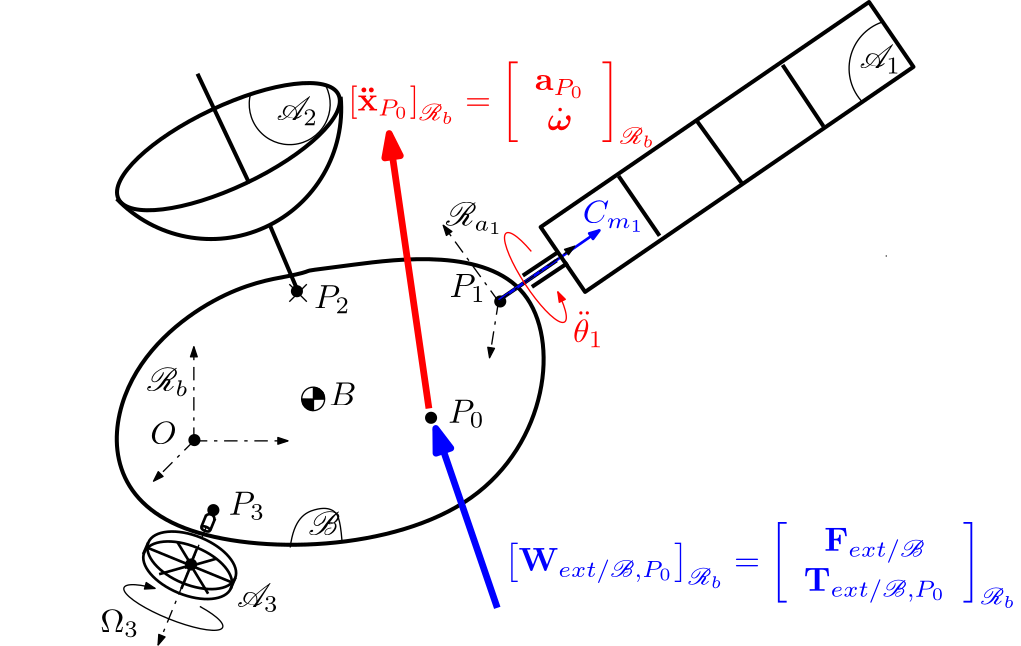

To address the general multibody system depicted in the first Figure of this tutorial, one port models can be extented to TITOP (Two Inputs-Two Outputs Ports) models (or more generally NINOP models: N Inputs- N-Ouputs Ports models). See also the tutorial 5: [***a short course on TITOP (Two-Input Two-Output Ports) models***](matlab:open('../Tutorial5/tutorial5.html'))***.***

### 2.1 Illustration in the single-axis case

Let us consider the spring-mass system $\mathcal A$ between the points $P$ and $C$as depicted in the following Figure.  Only motions along $\mathbf x$-axis are considered. 

                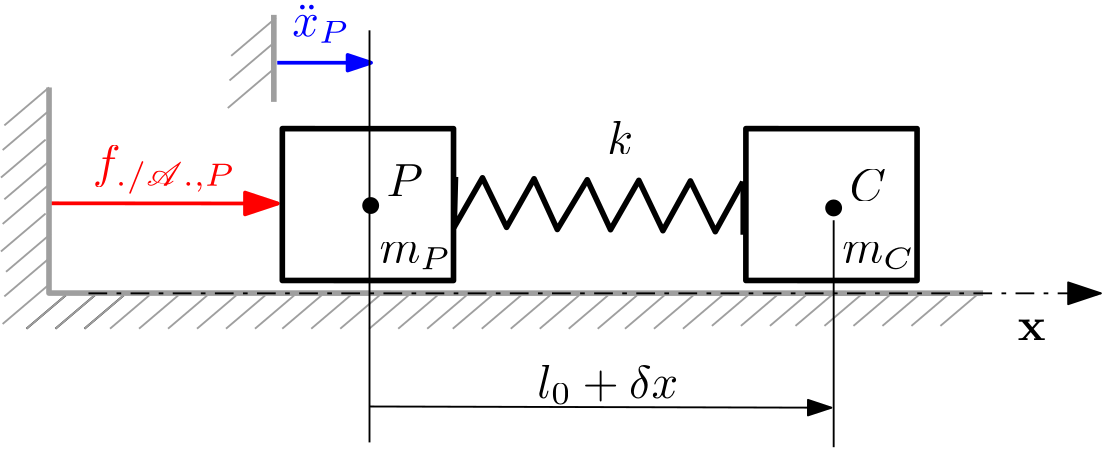

$k$, $m_P$, $m_C$ are the stiffness, the mass attached to the point $P$ and the mass attached to the point $C$ of the system $\mathcal A$, respectively. 

The objective is to compute the single input single output transfer function $G(\mathrm s)=M\!a^{\mathcal A}_P(\mathrm s)$ of $\mathcal A$ from  the inertial acceleration $\ddot x_P$ prescribed at the point $P$ (input in blue) to the force $f_{./\mathcal A,P}$ applied  to $\mathcal A$ at the point $P$ (output in ted).

Only variations around the equilibrium conditions are considered. $\delta x$ is the variation of the length of the vector $\overrightarrow{PC}$ w.r.t its length $l_0$ at rest. The equilibrium conditions are: $x_P=cte$, $x_C=x_p+l_0$, $\dot x_p=\dot x_C=0$.

The *Newton* principle applied on each of the 2 masses leads to:

- 
$$m_P\ddot x_p=f_{./\mathcal A,P}+k\delta x$$


- $m_C\ddot x_C=-k\delta x$.

Considering that $\delta \ddot x=\ddot x_C-\ddot x_P$, a state space representation of $G(\mathrm s)$, associated to the state vector $\mathbf x=[\delta x\quad \delta\dot x]^T$, reads:


$$\left[\begin{array}{c}\delta \dot x\\\delta \ddot x\end{array}\right]=\left[\begin{array}{cc} 0 & 1 \\ -\frac{k}{m_C} & 0\end{array}\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+\left[\begin{array}{cc} 0  \\  -1\end{array}\right] \ddot x_P$$


$f_{./\mathcal A,P}=\left[ -k\quad  0\right]\left[\begin{array}{c}\delta x\\ \delta\dot x\end{array}\right]+m_P\; \ddot x_P$,

and the transfer function $G(\mathrm s)$, after some algebra,  reads:

$G(\mathrm s) = m_P+m_C\frac{\omega_{c,P}^2}{\mathrm s^2+\omega_{c,P}^2}=\frac{F_{./\mathcal A,P}(\mathrm s)}{\ddot X_P(\mathrm s)}$ where $\omega_{c,P}=\sqrt{\frac{k}{m_C}}$ is the cantilever frequency  of $\mathcal A$ when it is cantilevered at point $P$.

$G(\mathrm s)$ is composed of $2$ terms:

- an **effective mass** $m_P$ rigidly attached to the point $P$ (where is prescribed the acceleration input),

- an **effective mass** $m_C$ which is flexible and characterized by the cantilevered frequency $\omega_{c,P}$.

Of course the DCgain of $G(s)$is the sum of the masss $m_P+m_C$ but if the system is "shaked" at the point $P$ with a frequency largely greater than $\omega_{c,P}$ then the apparent mass seen from the point $P$ is only the mass $m_P$.

Let us consider now a system $\mathcal S$ where the base $\mathcal B$, with a mass $m^{\mathcal B}$, holds the spring mass system $\mathcal A$. An actuator can apply a force $u\,(N)$ on the base $\mathcal B$. The inertial acceleration of the base is $\ddot x_P$. 

                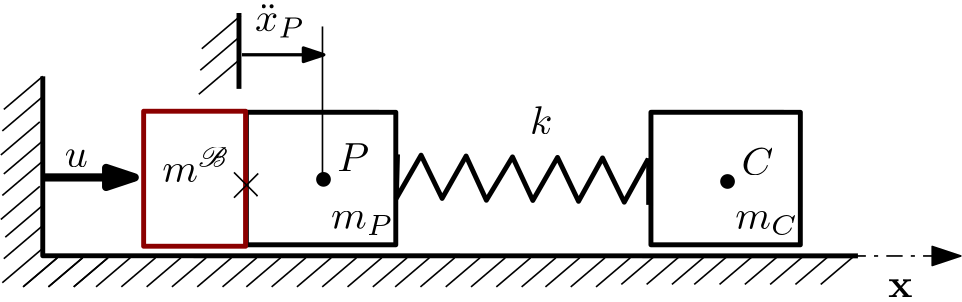

The dynamic model of the base $\mathcal B$considered alone is simply:

$\Sigma f_{ext/\mathcal B}=u+f_{\mathcal {A/B},P}=m^{\mathcal B} \ddot x_P$ and we will denote $D^{\mathcal B}_P=m^{\mathcal B}$ the direct dynamic model of the rigid base.

Considering that  $f_{./\mathcal A,P}=f_{\mathcal{B/A},P}=-f_{\mathcal {A/B},P}$ in the appendage model $G(\mathrm s)=M\!a^{\mathcal A}_P(\mathrm s)$, the direct dynamic model $M\!a^{\mathcal S}_P(\mathrm s)$ of the system $\mathcal S$ is just the sum of the direct dynamic models of $\mathcal  B$ and $\mathcal A$:

$M\!a^{\mathcal S}_P(\mathrm s)=D^{\mathcal B}_P+ M\!a^{\mathcal A}_P(\mathrm s)=m^{\mathcal B}+G(\mathrm s)=m^{\mathcal B}+m_P+m_C\frac{\omega_{c,P}^2}{\mathrm s^2+\omega_{c,P}^2}$.

The output of this model is $u$ and the input is $\ddot x_P$.

The inverse dynamic model ${[M\!a^{\mathcal S}_P]}^{-1}(\mathrm s)$, where the input is $u$ and the output is $\ddot x_P$, can be written as:

$[M\!a^{\mathcal S}_P]^{-1}(\mathrm s)=\frac{1}{D^{\mathcal B}_P+M\!a^{\mathcal A}_P(\mathrm s)}=\frac{{[D^{\mathcal B}_P]}^{-1}}{1+M\!a^{\mathcal A}_P(\mathrm s){[D^{\mathcal B}_P]}^{-1} }$.

This last formulation shows that the inverse dynamique of $\mathcal S$ is in fact the **inverse** dynamic model of the $\mathcal B$ in **feedback** with the **direct** dynamic model of $\mathcal A$ and can be represented by the following block diagram where:

- the model  $M\!a^{\mathcal A}_P(\mathrm s)$ of the appendage is detailled with the $3$ mechanical parameters $m_P$, $m_C$, $\omega_{c,p}$,

- the double integrator are added on $\ddot x_P$ to obtain the position variation $\delta x_P$ on the output and the motion vector $\delta\mathbf m_P$.

                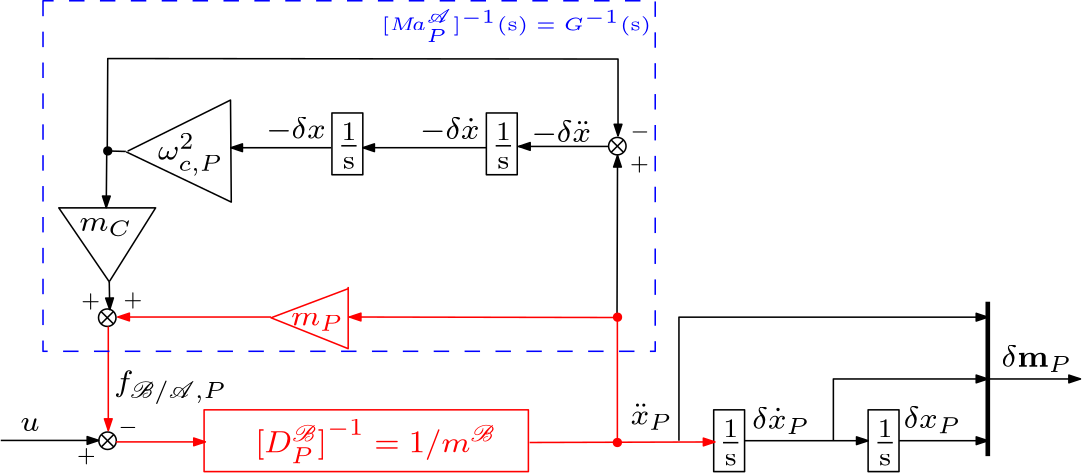

Note that this block-diagram representation is not interesting for simulation purpose since it exhibits an algebraic loop (represented in red in the previous Figure) which must be solved at each simulation step. The interest of this block diagram representation, which is in fact the core of the `SDTlib,` is twice:

- first, to have a structured model where each body is represented by its own sub-model depending only on its own mechanical parameters. Thus parametric variations on each of these mechanical parameter can be taken into account with a minimal occurence when the uncertain state-space model of the whole system is computed with, for instance, the function `ulinearize,`

- second,  the same approach can be used to "plug" any other spring-system to the base $\mathcal B$ as described in the following example.

Considering a base $\mathcal B$ holding $3$ spring-mass systems $\mathcal A_i$, $i=1,2,3$ as depicted in the following Figure. Each appendage $\mathcal A_i$ is characterized by 3 parameters $m_{P_i}$, $m_{C_i}$, $\omega_{c,p_i$ and the effective mass model $M\!a^{\mathcal A_i}_P(\mathrm s)$ (or $G_i(\mathrm s)$), previously defined.

                            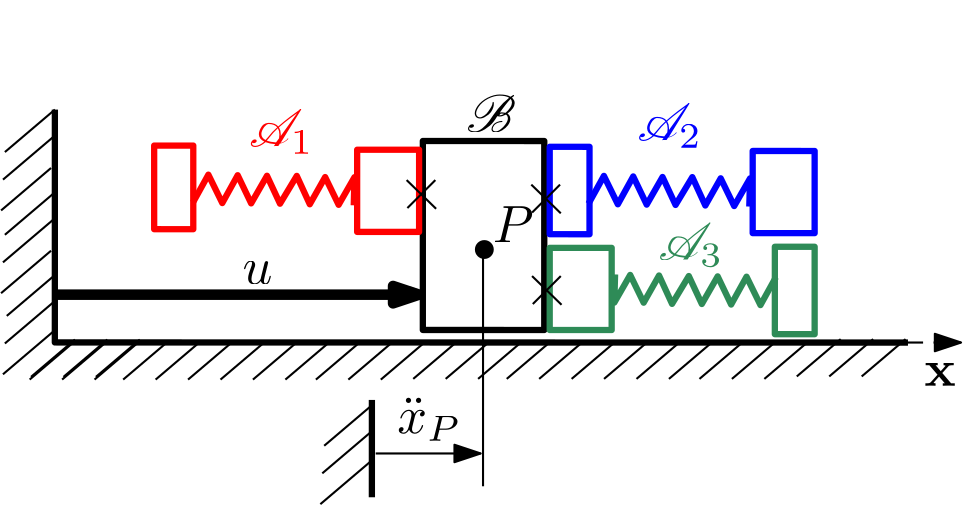

Then the model of the whole system taking account all the dynamic couplings between the sub-systems can be described by the following block-diagram representation.

                                    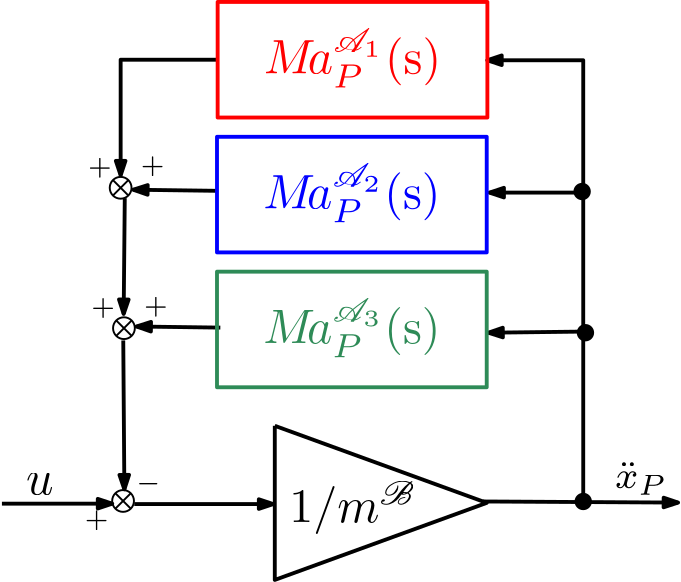

### 2.2 Six d.o.fs case

The previous block-diagram-based modelling approach can be directly extended to the 6 d.o.fs case while taking into account:

- the dynamics coupling between translations and rotations due to the geometry (lever-arm effect),

- the various frames in which are described the various bodies $\mathcal B$ ,$\mathcal A_i$ ,

- the 6 d.o.f.s behavior of the flexible modes of each flexible appendages $\mathcal A_i$.

Reconsidering the case of the clamped connection of a fexible appendage $\mathcal A$ on a rigid base $\mathcal B$ at the point $P$. The inverse dynamic model ${[\mathbf {M\!a}^{\mathcal S}_{O}]_{\mathcal R_b}}^{-1}(\mathrm s)$ of the system $\mathcal{S=B+A}$ at the point $O$ and projected in the frame $\mathcal R_b$ is described by the feedback loop depicted in the following Figure where the $6\times 6$ inverse dynamic model of the base $\left[\mathbf{D}_{O}^{\mathcal{B}}\right]^{-1}_{\mathcal{R}_b}$ is in feedback with the $6\times 6$ direct effective mass model $[\mathbf {M\!a}^{\mathcal A}_{P}]_{\mathcal R_a}(\mathrm s)$ of the appendage. The feedback loop contains also:

- the change of frame, defined by the DCM (Direction Cosine Matrix) $\mathbf P_{a/b}$, from $\mathcal R_a$ to $\mathcal R_b$ to obtain $[\mathbf {M\!a}^{\mathcal A}_{P}]_{\mathcal R_b}(\mathrm s)$,

- the transportation, defined by the kinematic model $\mathbf\tau_{PO}$, from the point $P$ to the point $O$ to obtain $[\mathbf {M\!a}^{\mathcal A}_{O}]_{\mathcal R_b}(\mathrm s)$.          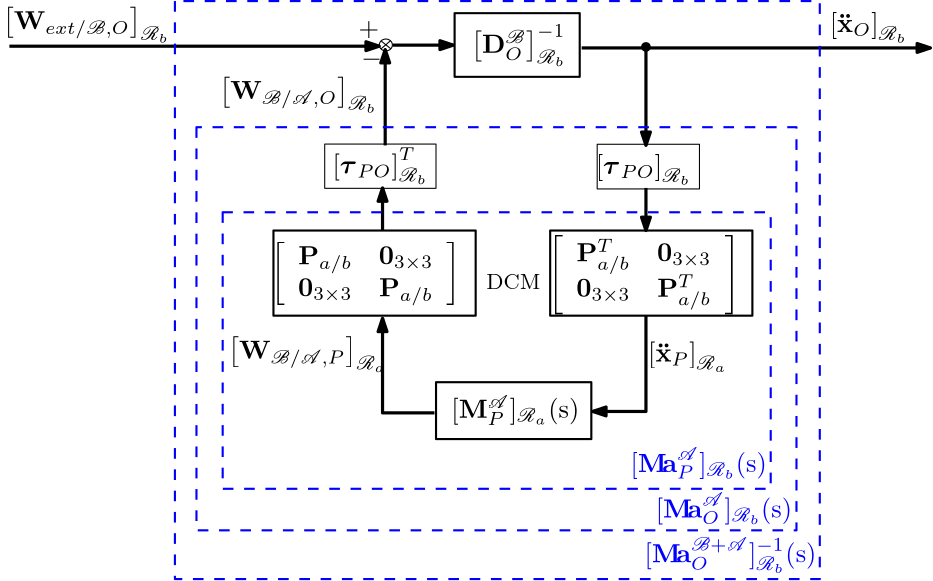

In this Figure:

- $\mathbf{D}^{\mathcal{B}}_{O}$ is the $6 \times 6$  rigid mass model of the body $\mathcal B$ at the point $O$: $\mathbf{D}^{\mathcal{B}}_{O}=\mathbf\tau_{BO}^T\left[\begin{array}{cc}m^{\mathcal{B}}\mathbf{1}_3 & \mathbf{0}_{3\times 3}\\ \mathbf{0}_{3\times 3} & [\mathbf{I}^{\mathcal{B}}_B] \end{array}\right]\mathbf\tau_{BO}$ where $B$, $m^{\mathcal B}$ and $\mathbf I^{\mathcal B}_B$  are the centre of mass, the mass and the inertia tensor at $B$, respectively. See also:

web Docmultiportrigidbody.html -new

- $\mathbf{\tau}_{BO}$ is the "rigid'' kinematic model between points $B$ and $O$: $\mathbf{\tau}_{BO}=\left[\begin{array}{cc} \mathbf{1}_3  & (^*\overrightarrow{BO})\\ \mathbf{0}_{3\times 3} & \mathbf{1}_3  \\ \end{array}\right]$ where $(^*\overrightarrow{BO})$ is the skew-symmetric matrix associated to vector from $B$ to $O$.

- $\mathbf{\tau}_{PO}$ is the "rigid'' kinematic model between points $P$ and $O$,

- $\mathbf P_{a/b}$ is the DCM (Direction Cosine Matrix) from the appendage frame $\mathcal R_a$ to the main body frame $\mathcal R_b$. See also:

web Doc6dcm.html -new

$\mathbf{M}_{P}^{\mathcal{A}}(\mathrm{s})$ is the $6\times 6$ effective mass model of the flexible appendage at the point $P$: $\mathbf{M\!a}^{\mathcal{A}}_P (\mathrm{s})=\mathbf{D}^{\mathcal{A}}_P-\sum_{i=1}^N \mathbf{l}_{i,P}^T\mathbf{l}_{i,P} \frac{\mathrm{s}^2}{\mathrm{s}^2+2\xi_i\omega_i \mathrm{s}+\omega_i^2}$  where:

- $\mathbf{l}_{i,P}$, $\omega_i$, $\xi_i$ are, respectively: the modal participation factors at point $P$, the frequencies and the damping ratios of the $N$ flexible modes of body $\mathcal{A}$,

- $\mathbf{D}^{\mathcal{A}}_P=\mathbf\tau_{AP}^T\left[\begin{array}{cc}m^{\mathcal{A}}\mathbf{1}_3 & \mathbf{0}_{3\times 3}\\ \mathbf{0}_{3\times 3} & \mathbf{I}^{\mathcal{A}}_A \end{array}\right]\mathbf \tau_{AP}$  is the total static mass of the appendage $\mathcal A$ at the point $P$ where $A$, $m^{\mathcal A}$ and $\mathbf I^{\mathcal A}_A$  are the centre of mass, the mass and the inertia tensor at $A$, respectively.

All these data required to build the model $\mathbf{M}_{P}^{\mathcal{A}}(\mathrm{s})$ can be provided by:

- the user. See also the tutorial 2: [***a spacecraft with 2 symmetrical rotating solar arrays***](matlab:open('../Tutorial2/tutorial2.html'))***,***

- or provided by a NASTRAN output file (file `***.f06`) thanks to a NASTRAN/SIMULINK interface included in the `SDTlib`. See also the tutorial 4:[ ***a spacecraft with 2 symmetrical rotating solar arrays defined by a NASTRAN model***](matlab:open('../Tutorial4/tutorial4.html')) of the **full version** of the `SDTlib`.

The state-space representation and block-diagram representation of  the appendage model $\mathbf{M}_{P}^{\mathcal{A}}(\mathrm{s})$ are detailled in the help of the block` 1 port flexible body. `See also:

web Doconeportflexiblebody.html -new

### 2.3 Revolute joints

In the case where the appendage $\mathcal A$ is connected to the base through a revolute joint, let us denote:

-  $\mathbf r_a$the direction of the joint axis (unitary vetor)

- $[\mathbf{r}_a]_{\mathcal{R}_a}=[x_{r_a},\;y_{r_a},\,z_{r_a},]^T$ the projection of $\mathbf r_a$ in $\mathcal R_a$, 

- $\theta$ the angular configuration of the joint around $\mathbf r_a$.

Then, the revolute joint dynamics can be taken into account directly in the previous direct dynamic model $\mathbf{M\!a}_{P}^{\mathcal{A}}(\mathrm{s})$ of the appendage by considering that:

- the inertial angular acceleration $\dot\mathbf \omega$ of the point $P$ is augmented by the relative acceleration $\ddot \theta$ around $\mathbf r_a$,

- the driving torque $C_m$ inside the revolute joint is the projection alond $\mathbf r_a$ of the interaction torque $\mathbf T_{\mathcal{B/A},P}$ applied by $\mathcal B$ on $\mathcal A$ at the point $P$: 

$\left[\mathbf{G}^{\mathcal{A}+r}_P\right]_{\mathcal{R}_a}(\mathrm{s})=\left[\begin{array}{c}\mathbf{1}_6\\ 0\;0\;0\;x_{r_a}\;y_{r_a}\;z_{r_a}\end{array}\right]\left[\mathbf{M\!a}^{\mathcal{A}}_P \right]_{\mathcal{R}_a}(\mathrm{s})\left[\begin{array}{cc}\mathbf{1}_6 & \begin{array}{c}0\\0\\0\\x_{r_a}\\y_{r_a}\\z_{r_a}\end{array}\end{array}\right]$. 

$\mathbf{G}^{\mathcal{A}+r}_P(\mathrm{s})$ is $7\times 7$ direct dynamic model of the appendage with the revolute joint. Its inputs are the acceleration twist $\ddot\mathbf x_P$ and $\ddot\theta$. Its outputs are the interaction wrench $\mathbf{W}_{\mathcal{B}/\mathcal{A},P}$ and $C_m$.

From a practical point of view, the last channel needs to be inverted. That can be done thanks to the function `invio`. 

**Notation:**

- $\mathbf G^{-1_{\mathbf I}}(\mathrm s)$ is the model $\mathbf G(\mathrm s)$ where the channels numbered in the vector of indexes $\mathbf I$ are inverted. See also:

web docInvio.html -new

The joint angular configuration $\theta$ is taken into account by the DCM $\mathbf P_{\mathbf r_a}(\theta)$ associated to a rotation of $\theta\,(rad)$ around $\mathbf r_a$. $\theta$ can be declared as a varying parameter (using the function `ureal`) in order to have a linear model valid for a full revolution of the joint. Then, $\mathbf P_{\mathbf r_a}(\theta)$ is a varying $3\times 3$ matrix, parameterized according to $\sigma_4=\tan{\frac{\theta}{4}$ in order to be represented by an normalized LFT (Linear Fractional Transformation) with $-1\le\sigma_4\le 1$. See also:

web Doc3zurotation.html -new

Finally the inverse dynamic  model $[\mathbf M^{\mathcal S}_{O}]_{\mathcal R_b}^{-1}(\mathrm s,\theta)$ of the system $\mathcal S$ composed of the main body $\mathcal B$, the revolute joint $r$ and the appendage $\mathcal A$, at the point $O$ and projected in the main body frame, can be represented by the following block-diagram.

        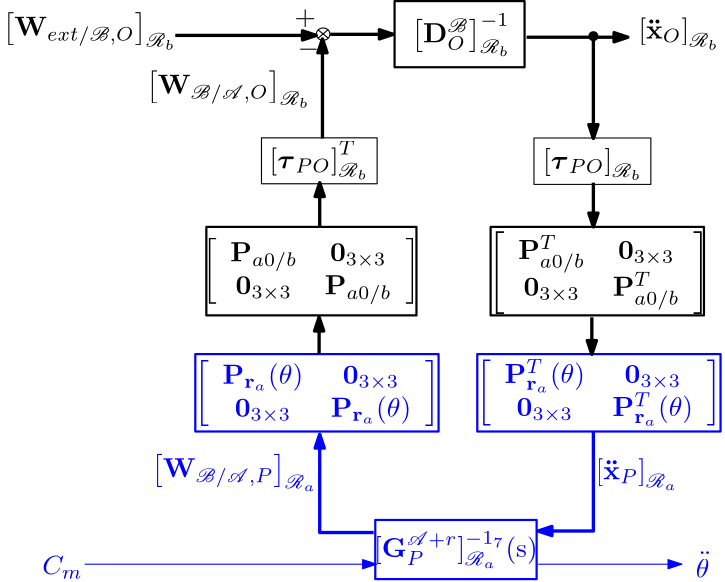

In this block-diagram $\mathbf P_{a0/b$ is the DCM between $\mathcal R_a$ and $\mathcal R_b$ when $\theta=0$.

The appendage and its revolute joint (the blue part in the block-diagram) can also be dissociated and modelled by the direct dynamic model $\mathbf{M\!a}_{P}^{\mathcal{A}}(\mathrm{s})$ of the appendage in feedback connection with the TITOP model of a revolute joint, thus avoiding the $7$-th channel inversion. See also the section 2.2 of the tutorial 5: [***a short course on TITOP (Two-Input Two-Output Ports) models***](matlab:open('../Tutorial5/tutorial5.html'))***.***

The sub-library `Predefined subsystems` of the `SDTlib` contains the models of rigid/flexible bodies taking into account a revolute joint at the connection point which are used in the various tutorials of the `SDTlib` .

### 2.4 Prismatic joints

Prismatic joints are now included in the **full version** of the `SDTlib`.

In the case where the appendage $\mathcal A$ is connected to the base through a prismatic joint, let us denote:

-  $\mathbf t_a$ the direction of the joint axis (unitary vetor)

- $[\mathbf{t}_a]_{\mathcal{R}_a}=[x_{t_a},\;y_{t_a},\,z_{t_a},]^T$ the projection of $\mathbf t_a$ in $\mathcal R_a$, 

- $x$ the translation configuration of the joint along $\mathbf t_a$.

Then, the prismatic joint dynamics can be taken into account directly in the previous direct dynamic model $\mathbf{M}_{P}^{\mathcal{A}}(\mathrm{s})$ of the appendage by considering that:

- the inertial linear acceleration $\mathbf a_P$ of the point $P$ is augmented by the relative acceleration $\ddot x$ along $\mathbf t_a$,

- the driving force $F_m$ inside the prismatic joint is the projection alond $\mathbf t_a$ of the interaction force $\mathbf F_{\mathcal{B/A},P}$ applied by $\mathcal B$ on $\mathcal A$ at the point $P$: 

$\left[\mathbf{G}^{\mathcal{A}+p}_P\right]_{\mathcal{R}_a}(\mathrm{s})=\left[\begin{array}{c}\mathbf{1}_6\\ x_{t_a}\;y_{t_a}\;z_{t_a}\;0\;0\;0\end{array}\right]\left[\mathbf{M\!a}^{\mathcal{A}}_P \right]_{\mathcal{R}_a}(\mathrm{s})\left[\begin{array}{cc}\mathbf{1}_6 & \begin{array}{c}x_{t_a}\\y_{t_a}\\z_{t_a}\\0\\0\\0\end{array}\end{array}\right]$. 

$\mathbf{G}^{\mathcal{A}+p}_P(\mathrm{s})$ is $7\times 7$ direct dynamic model of the appendage with the prismatic joint. Its inputs are the acceleration twist $\ddot\mathbf x_P$ and $\ddot x$. Its outputs are the interaction wrench $\mathbf{W}_{\mathcal{B}/\mathcal{A},P}$ and $F_m$.

From a practical point of view, the last channel needs to be inverted. 

The joint linear configuration $x$ is taken into account by the kinematic model $\mathbf \tau_{PP_0}(x)=\mathbf \tau_{-x\mathbf t_a}$ associated to the translation of $x\,(m)$ along $\mathbf t_a$ (the point $P$ on the output slider of the prismatic joint coincides with the point $P_0$ on the input slider if $x=0$). $x$ can be declared as a varying parameter (using the function `ureal`) in order to have a linear model valid for any translation configuration of the joint.

Finally the inverse dynamic  model $[\mathbf M^{\mathcal S}_{O}]_{\mathcal R_b}^{-1}(\mathrm s,x)$ of the system $\mathcal S$ composed of the main body $\mathcal B$, the prismatic joint $p$ and the appendage $\mathcal A$, at the point $O$ and projected in the main body frame, can be represented by the following block-diagram.

            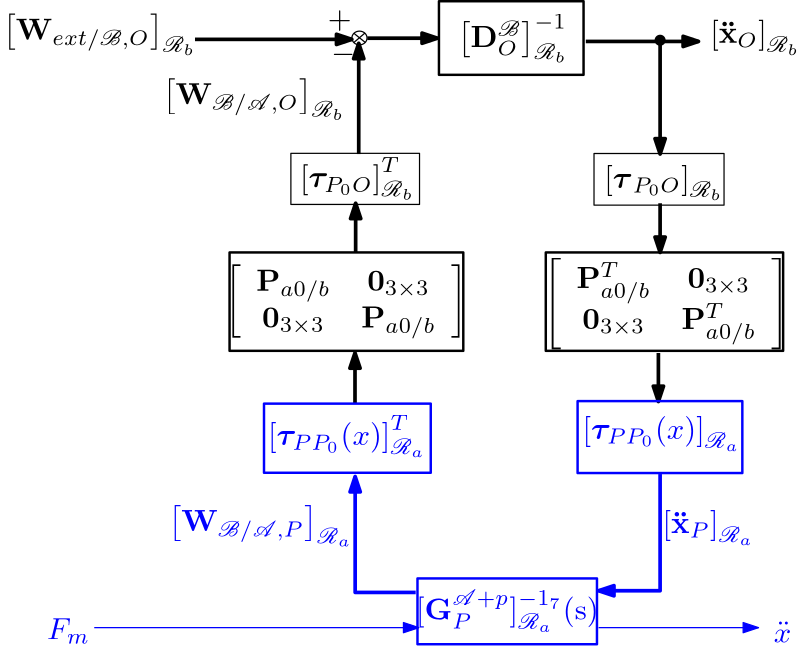

In this block-diagram $\mathbf P_{a0/b$ is the DCM between $\mathcal R_a$ and $\mathcal R_b$.

The appendage and its primatic joint (the blue part in the block-diagram) can also be dissociated and modelled by the direct dynamic model $\mathbf{M\!a}_{P}^{\mathcal{A}}(\mathrm{s})$ of the appendage in feedback connection with the TITOP model of a prismatic joint, thus avoiding the $7$-th channel inversion. See also the tutorial 13: [***the slider-crank mechanism***](matlab:open('../Tutorial13/tutorial13.html'))***.***

The sub-library `Predefined subsystems` of the `SDTlib` contains the models of rigid/flexible bodies taking into account a primsatic joint at the connection point.

### 2.5 Summary

- The SDTlib is based on a highly **structured **block-diagram representation of the multibody systems. 

- The LFT (Linear Fractional Transformation) of the DCM, thanks to the parametrization in $\sigma=\tan{\frac{\theta}{4}$, allows to obtain a linear model valid for any angular configurations of the revolute joints.

- the various dynamic or geometric parameters introduced in the previous sections, **except** the DCMs ($\mathbf P_{a/b}$) and the directions of the revolute joint axes ($\mathbf r_a$), can be declared as uncertain or varying parameters (using the function `ureal`). Thus, the **mechanical parameter** vector $\mathbf \Delta$, used in the general model $\mathbf M^{\mathcal S}(\mathrm s,\mathbf \theta_{ref},\mathbf\Delta)$, can be composed of : $\mathbf\Delta=\{m^{\mathcal B}, [\mathbf I^{\mathcal B}_B]_{\mathcal R_b},[\overrightarrow{BP_0}]_{\mathcal R_b}, [\overrightarrow{OP}]_{\mathcal R_b},m^{\mathcal A}, [\mathbf I^{\mathcal A}_A]_{\mathcal R_a},[\overrightarrow{AP}]_{\mathcal R_a}, \omega_i,\xi_i,\mathbf l_{i,P},\cdots\}$.

## 3. References

- Girard, A.: [Modal effective mass models in structural dynamics](https://ui.adsabs.harvard.edu/abs/1991imac.conf...45G/abstract) . In: International Modal Analysis  Conference (IMAC), 9th, Florence, Italy, Apr. 15-18, 1991, Proceedings.  Vol. 1 (A93-29227 10-39), p. 45-50

- Alazard, Daniel and Cumer, Christelle and Tantawi, Khalid.  [*Linear dynamic modeling of spacecraft with various flexible appendages and on-board angular momentums.*](https://www.researchgate.net/publication/27813087_Linear_dynamic_modeling_of_spacecraft_with_various_flexible_appendages_and_on-board_angular_momentums)     (2008) In: 7th International ESA Conference on Guidance, Navigation &  Control Systems (GNC 2008), 2 June 2008 - 5 June 2008  (Tralee,  Ireland). 

- Guy, Nicolas and Alazard, Daniel and Cumer, Christelle and Charbonnel, Catherine.  [*Dynamic modeling and analysis of spacecraft with variable tilt of flexible appendages.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/4507/dynamic-modeling-and-analysis-of-spacecraft-with-variable-tilt-of-flexible-appendages)     (2014) Journal of Dynamic Systems Measurement and Control, 136 (2). ISSN 0022-0434 

- Cumer, Christelle and Alazard, Daniel and Grynadier, Alain and Pittet, Christelle.  [*Codesign mechanics / attitude control for a simplified AOCS preliminary synthesis.*](https://openscience.isae-supaero.fr/Default/doc/SYRACUSE/7793/codesign-mechanics-attitude-control-for-a-simplified-aocs-preliminary-synthesis)     (2014) In: ESA GNC 2014 - 9th International ESA Conference on Guidance,  navigation & Control Systems, 2 June 2014 - 6 June 2014  (Porto,  Portugal). 